%Universidad del Cauca - 2021-1
%Teoria de las telecomunicaciones 1
%Trabajo 1 - Grupo 12 - Nicolas Chicaiza y Nicolas Zambrano

clear; %Limpio Espacio de trabajo
clc;

narm=100; %Numero de armonicos tomados para reconstruir la señal

A=1; %Amplitud rampa

Tr=4; %Periodo rampa
To=4; %Periodo ceros
T=Tr+To; %Periodo de la señal

f=1/T; %Frecuencia
fs=(1/T):1/T:(narm/T); %Normalizacion vector de Frecuencia

np=T*0.01; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
t=-(2*T):np:(2*T); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)

parsacum=0;

ramp=(A/Tr)*t; %Defino la pendiente de las rampas y creo el vector rampa con respecto al tiempo
ps=ramp.*rectpuls(t-(Tr/2),Tr); %Acoto el vector rampa con un pulso rectangular de origen en 0 y ancho Tr
dds=zeros(size(t)); %Incializo variable
shft=0; % Incializo variable
for k=-2:1:1 %en este ciclo roto el vector rampa ps y voy generando la funcion diente de sierra repetida por 4 periodos
shft=T*k*(1/np);
dds=dds+circshift(ps,fix(shft)); %sumatoria de generacion
end

%---------------------------CALCULO DE COEFICIENTES--------------------------
%---------------------------Bn--------------------------
syms x n;
dib=(A*x/Tr)*sin(2*pi*n*f*x); %Expresion dentro de la integral b 'dib'
bn=(2/T)*int(dib,[0 Tr]); %Integral definida en el periodo de la rampa
bn=simplify(bn)

$$bn = \frac{\sin\left(\pi \,n\right)-\pi \,n\,\cos\left(\pi \,n\right)}{n^{2}\,\pi^{2}}$$

%---------------------------An--------------------------
syms x n;
dia=(A*x/Tr)*cos(2*pi*n*f*x); %Expresion dentro de la integral a 'dia'
an=(2/T)*int(dia,[0 Tr]);
an=simplify(an)

$$an = -\frac{2\,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}-\pi \,n\,\sin\left(\pi \,n\right)}{n^{2}\,\pi^{2}}$$

%---------------------------Ao--------------------------
syms x n;
diao=(A*x/Tr); %Expresion dentro de la integral a 'diao'
ao=(2/T)*int(diao,[0 Tr])

$$ao = \frac{1}{2}$$

ao=double(ao);
%-----------------------------------------------------------------------------

%--------------------Ciclo sumatoria coeficientes---------------------------
Sefu=ao/2;% Inicializo con el nivel DC
for n=1:narm %Ciclo de sumatoria (desde n=1 hasta el numero de armonicos deseados (narm))
anf=subs(an);%Evaluo el coeficiente a en n
anf=double(anf);%Convierto el coeficiente en numero para optimizar calculos
Sefua=anf*cos(2*pi*n*f*t);
bnf=subs(bn);
bnf=double(bnf);
Sefub=bnf*sin(2*pi*n*f*t);
mag(n)=sqrt(bnf^2+anf^2);%Vector del espectro de magnitud
Sefu=Sefu+(Sefua+Sefub);
parsacum=parsacum+(mag(n)^2);
end
%-----------------------------------------------------------------------------

%---------------------------Convergencia de la serie a la funcion--------------------------
dipc=(abs(A*x/Tr))^2; %Expresion dentro de la integral pc 'dipc'
parscon=(2/(T))*int(dipc,[0 Tr]); %Integral del lado continuo de la igualdad de parseval
parscon=double(parscon); %Valor del lado continuo de la igualdad de parseval

parsdis=((ao^2)/2)+parsacum; %Valor del lado serial de la igualdad de parseval

relpars=(parsdis/parscon)*100 %porcentaje de convergencia en la igualdad de parseval

relpars = 99.6975

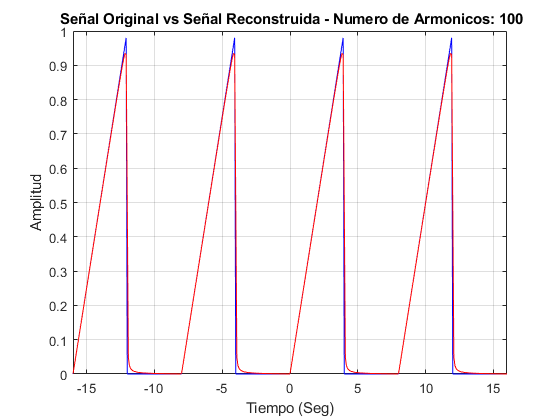


%-----------------------------------------------------------------------------


%--------------------Graficacion de Resultados---------------------------
plot(t,dds,'b',t,Sefu,'r'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-2*T 2*T]); %Graficacion de Resultados
title(['\bf Señal Original vs Señal Reconstruida - Numero de Armonicos: ',num2str(n),'']);

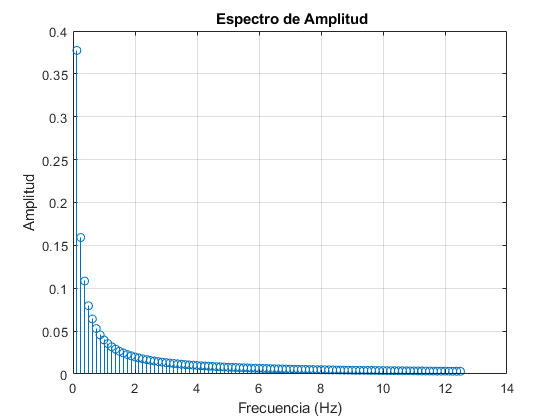

stem(fs,mag),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud; %Graficacion de Resultados
title('\bf Espectro de Amplitud');

%-----------------------------------------------------------------------------